# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 구은총**

**학번**** : 201710871**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 :  https://github.com/9sgun?tab=repositories**

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

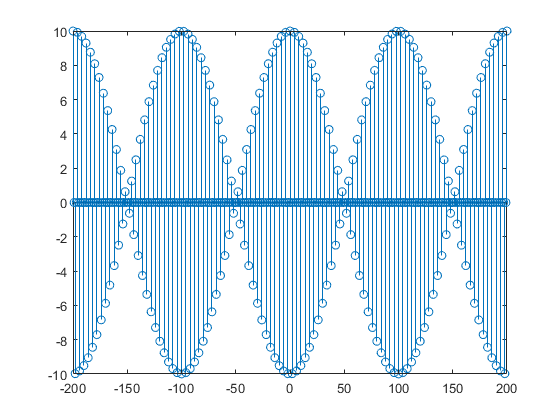


n = -200:200;
x5 = 5*(cos(0.49*pi*n) + cos(0.51*pi*n));
figure();
stem(n,x5);

2) 

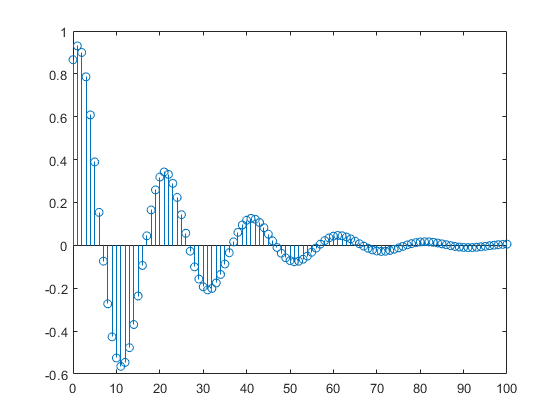

n = 0:100;
x7 = exp(-0.05*n) .* sin(0.1*pi*n + pi/3);
figure();
stem(n,x7);

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

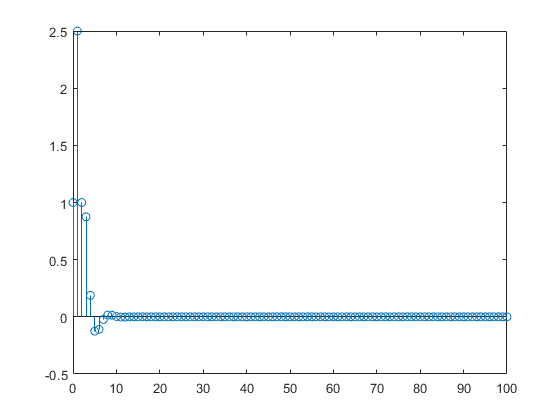

n = 0:100;
a = [1 -0.5 0.25]; b = [1 2 0 1];
h = impz(b,a,n);
figure();
stem(n,h);

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

sum(abs(h))     % 결과값이 발산하지 않으므로 stable 하다.

ans = 5.8571

3) 만약 이 시스템의 입력이 $x\left(n\right)=\left\lbrack 5+3\cos \left(\left.\left.0\ldotp 2\pi n\right)+4\sin \left(0\ldotp 6\pi n\right)\right\rbrack u\left(n\right)\right)\right\rbrack$이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

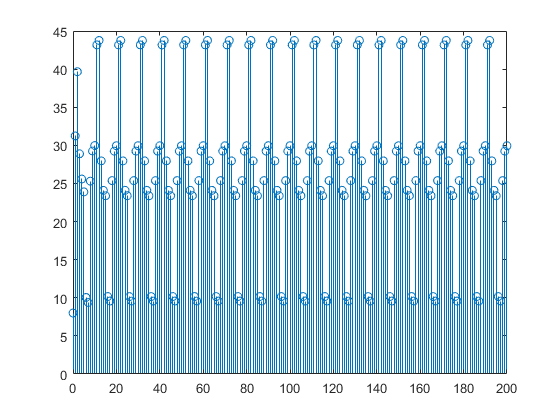

a = [1 -0.5 0.25]; b = [1 2 0 1];
n = 0:200;
x = 5 + 3*cos(0.2*pi*n) + 4*sin(0.6*pi*n);
y = filter(b,a,x);
figure();
stem(n,y);

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 


$$y\left(n\right)=\frac{{\left(0\ldotp 8\right)}^{n+1} -{\left(-0\ldotp 9\right)}^{n+1} }{1\ldotp 7}$$


n = 0:50;
y = ((0.8 .^ (n+1)) - ((-0.9) .^ (n+1))) / 1.7

y =     1.0000   -0.1000    0.7300   -0.1450    0.5401   -0.1584    0.4047   -0.1545    0.3068   -0.1419    0.2351   -0.1257    0.1819   -0.1087    0.1418   -0.0924    0.1113   -0.0777    0.0879   -0.0647    0.0698   -0.0536    0.0556   -0.0441    0.0445   -0.0362    0.0356   -0.0296    0.0286   -0.0242    0.0230   -0.0197    0.0186   -0.0161    0.0150   -0.0131    0.0121   -0.0106    0.0098   -0.0086    0.0079   -0.0070    0.0064   -0.0057    0.0052   -0.0046    0.0042   -0.0037    0.0034   -0.0030


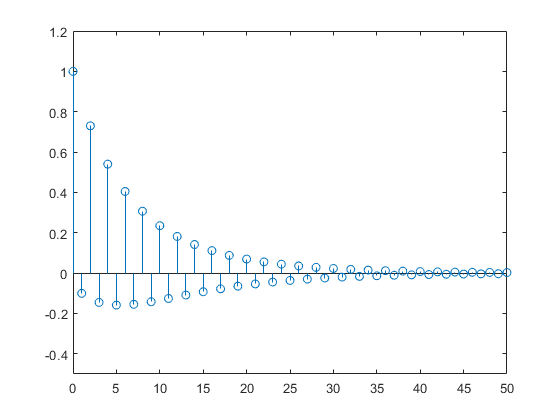

figure();
stem(n,y); axis([0 50 -0.5 1.2]);

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

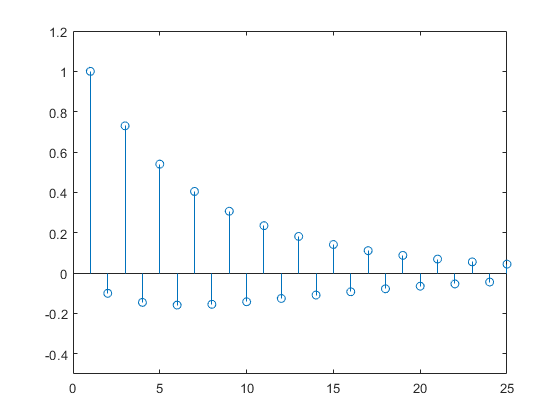

n2 = 0:25;
y2 = conv(x,h);
stem(y); axis([0 25 -0.5 1.2]);

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 


$$\begin{array}{l}
h\left(n\right)={\left(-0\ldotp 9\right)}^n u\left(n\right)\\
\left(-0\ldotp 9\right)h\left(n-1\right)={\left(-0\ldotp 9\right)}^n u\left(n-1\right)\\
h\left(n\right)-\left(-0\ldotp 9\right)h\left(n-1\right)=\delta \left(n\right)\\
y\left(n\right)+0\ldotp 9y\left(n-1\right)=x\left(n\right)
\end{array}$$
 

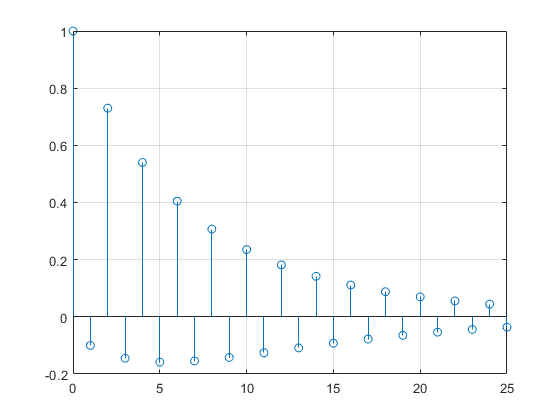

n3 = 0:25;
b = [1]; a = [1 0.9];
x = (0.8) .^ n3;
y = filter(b,a,x);
stem(n3,y); grid;

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$ : even sequence  ㅡㅡ> Phase of Fourier Transform should be zero.

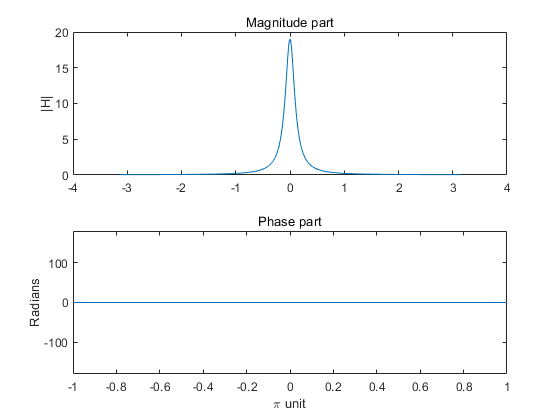

n = -300:300; w = [-500:500]*pi/500;
abs_n = abs(n);
h = (0.9) .^ abs_n;

H = h*exp(-j*n'*w);
figure();
subplot(2,1,1);
plot(w,abs(H));
ylabel('|H|'); title('Magnitude part');
subplot(2,1,2);
plot(w,angle(H)*180/pi); axis([-1 1 -180 180]);
xlabel('\pi unit'); ylabel('Radians'); title('Phase part');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

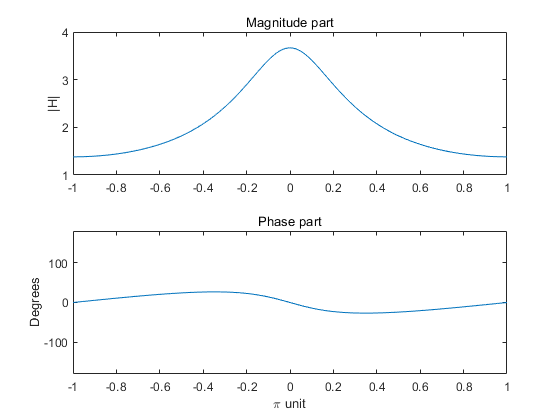

n = 0:100; w = [-500:500]*pi/500;
h = ((0.5).^n + (0.4).^n);
H = h*exp(-j*n'*w);
figure();
subplot(2,1,1);
plot(w/pi,abs(H));
ylabel('|H|'); title('Magnitude part');
subplot(2,1,2);
plot(w/pi,angle(H)*180/pi); axis([-1 1 -180 180]);
xlabel('\pi unit'); ylabel('Degrees'); title('Phase part');

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

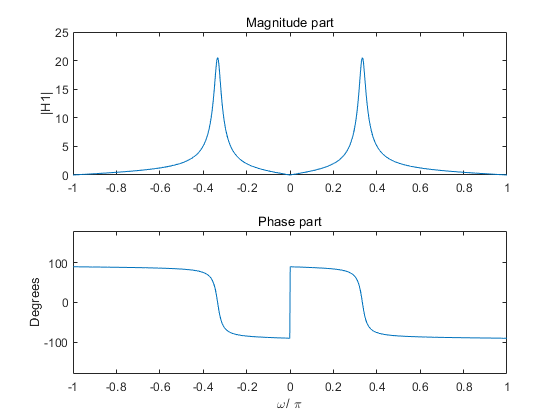

a = [1 -0.95 0.9025]; b = [1 0 -1]; w = [-1000:1000]*pi/1000;
H1 = freqresp(b,a,w);
figure();
subplot(2,1,1);
plot(w/pi,abs(H1)); axis([-1 1 0 25]);
ylabel('|H1|'); title('Magnitude part');
subplot(2,1,2);
plot(w/pi,angle(H1)*180/pi); axis([-1 1 -180 180]);
xlabel('\omega/ \pi'); ylabel('Degrees'); title('Phase part');

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^l y\left(n-l\right)$

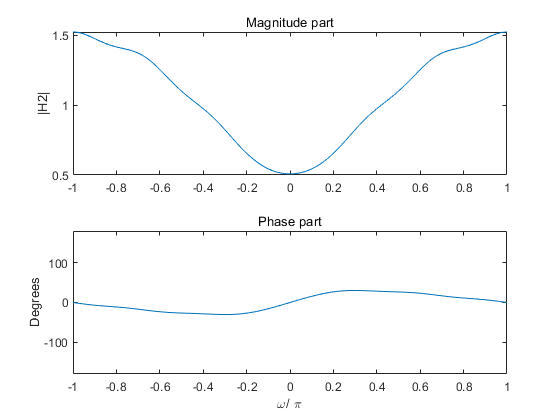

n = 0:5; w = [-1000:1000]*pi/1000;
a = (0.5).^n; b = [1];
H2 = freqresp(b,a,w);
figure();
subplot(2,1,1);
plot(w/pi,abs(H2));
ylabel('|H2|'); title('Magnitude part');
subplot(2,1,2);
plot(w/pi,angle(H2)*180/pi); axis([-1 1 -180 180]);
xlabel('\omega/ \pi'); ylabel('Degrees'); title('Phase part');

5. (P3.17) 

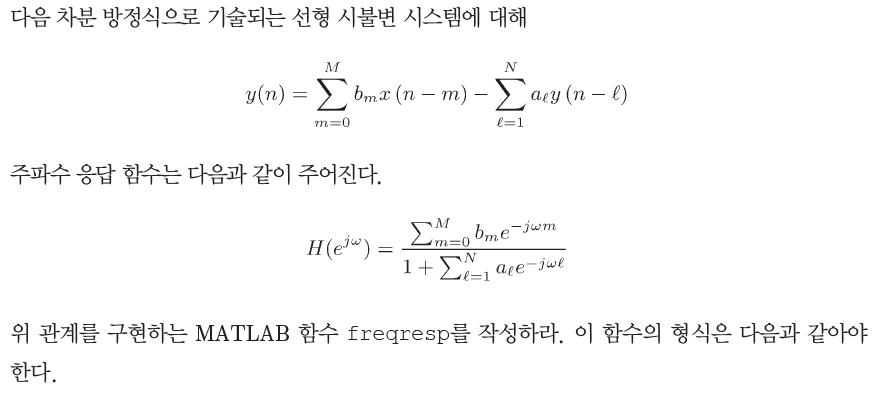

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array
b = b(:)'; a = a(:)';
l = 0:length(a)-1; m = 0:length(b)-1;
denom = a * exp(-j*l'*w);     % 분모
num = b * exp(-j*m'*w);           % 분자
H = num ./ denom;
end